# Image Labeler App

#### Github Repository: [**https://github.com/rrabbi2021/MATLAB_Assignment2**](https://github.com/rrabbi2021/MATLAB_Assignment2)

#### **Youtube Video: **[https://youtu.be/wRFAGtq3H9s?si=GbQtyBEyoUrSnQWR](https://youtu.be/wRFAGtq3H9s?si=GbQtyBEyoUrSnQWR)

#### Load image and open image labeler app

% Prompt the user to select the directory containing images
disp('Please select the directory containing images.');

Please select the directory containing images.


imageDir = uigetdir();

% Get the list of files and directories in the selected directory
filesAndDirs = dir(imageDir);

% Filter out directories
files = filesAndDirs(~[filesAndDirs.isdir]);

% Extract file names
fileNames = {files.name};

% Check if any files are found
if isempty(fileNames)
    disp('No image files found in the selected directory.');
    return;
end

% Ask the user if they want to open the Image Labeler App
choice = questdlg('Do you want to open the Image Labeler App to label the images?', 'Open Image Labeler App', 'Yes', 'No', 'Yes');

if strcmp(choice, 'Yes')
    % Open the Image Labeler App for the selected directory
    disp('Opening the Image Labeler App...');
    imageLabeler(imageDir);
else
    disp('You chose not to open the Image Labeler App.');
end

You chose not to open the Image Labeler App.


#### Prompt user to select necessary files 

% Prompt the user to select the original image file
disp('Please select the original image file.');

Please select the original image file.


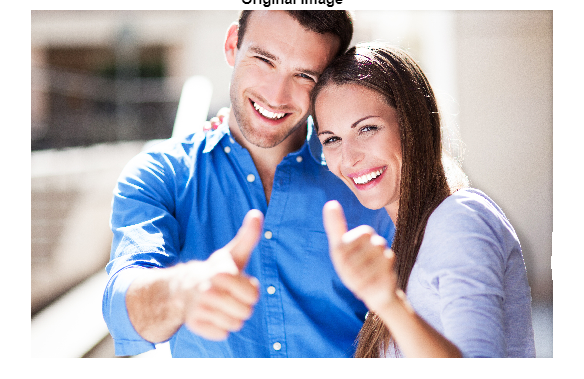

[originalFileName, originalFilePath] = uigetfile('*.jpg;');
originalImageFile = fullfile(originalFilePath, originalFileName);

% Read and display the original image
y = imread(originalImageFile);
imshow(y);
title('Original Image'); % Add title to figure

xlim([1 size(y, 2)]);
ylim([1 size(y, 1)]);


% Prompt the user to select the label definitions file
disp('Please select the label definitions file (.mat).');

Please select the label definitions file (.mat).


[fileName, filePath] = uigetfile('*.mat');
labelDefinitionsFile = fullfile(filePath, fileName);

#### Load Ground Truth Labels


% Load label definitions from the selected file
load(labelDefinitionsFile);

% Load ground truth labels
gTruth = load(labelDefinitionsFile);

% Display information about the ground truth labels
disp('Ground truth labels loaded successfully.');

Ground truth labels loaded successfully.


#### Read and Display Images

% Prompt the user to select the labeled image file
disp('Please select the labeled image file (.png).');

Please select the labeled image file (.png).


[labeledFileName, labeledFilePath] = uigetfile('*.png');
labeledImageFile = fullfile(labeledFilePath, labeledFileName);

% Read and display a labeled image
x = imread(labeledImageFile);
disp(size(x));

        3744        5616



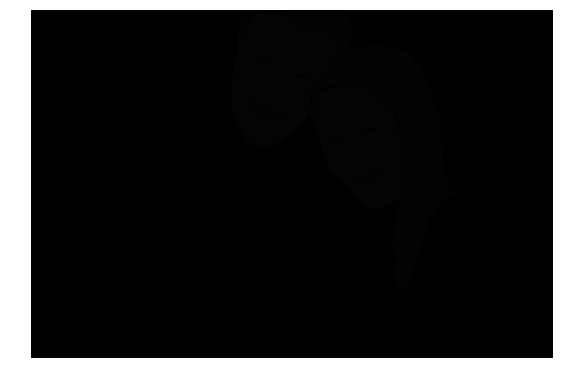

imshow(x);

#### Define ClassNames and Colormap

% Define ClassNames and Colormap
classNames = {'eyes', 'teeth', 'hair', 'face'}; % Define ClassNames
cmap = jet(numel(classNames)); % Create a colormap


#### Perform Histogram Equalization

x_histeq = histeq(x); % Histogram equalization


#### Overlay Labels on Image

B = labeloverlay(x_histeq, x, 'Transparency', 0.8, 'Colormap', cmap); % Overlay Labels on Image


#### Display Labeled Image

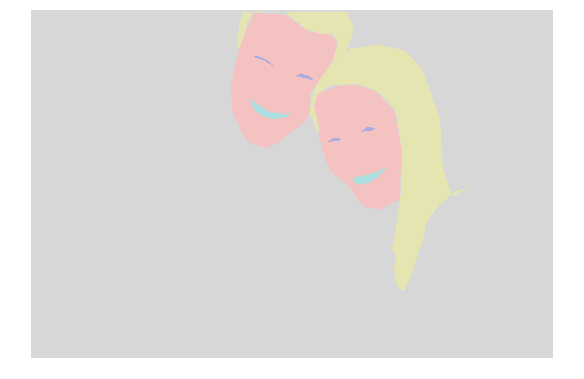

figure; % Create figure
title('Training Labels'); % Add Title to figure
imshow(B); % Display the labeled image

#### Display Colorbar

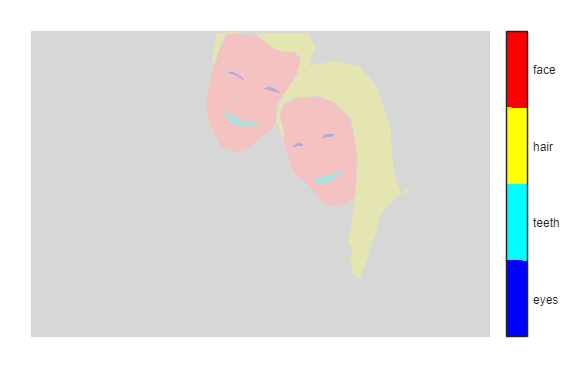

N = numel(classNames);
ticks = 1/(N*2):1/N:1;
colorbar('TickLabels', cellstr(classNames), 'Ticks', ticks, 'TickLength', 0, 'TickLabelInterpreter', 'none');
colormap(cmap);

xlim([1 size(y, 2)]);
ylim([1 size(y, 1)]);